Séance 3 Projet MSA

clear all

N = 1024;
VectN = 1:N;
sigmaBcarre = 0.5;
a = 0.5; % coefficient du filtre AR1
Nu0 = 0.05;


BruitB = BruitBlanc(N,sigmaBcarre);

BBfiltreAR1 = AR1(a, BruitB);

[Cx, pVectBBf ]= BiasedCrossCorr(BBfiltreAR1);

[a, v] = YuleWalkerSolver(Cx, 10)

MatCov =     0.6218    0.3146    0.1500    0.0782    0.0539    0.0410    0.0471    0.0455    0.0450    0.0361
    0.3146    0.6218    0.3146    0.1500    0.0782    0.0539    0.0410    0.0471    0.0455    0.0450
    0.1500    0.3146    0.6218    0.3146    0.1500    0.0782    0.0539    0.0410    0.0471    0.0455
    0.0782    0.1500    0.3146    0.6218    0.3146    0.1500    0.0782    0.0539    0.0410    0.0471
    0.0539    0.0782    0.1500    0.3146    0.6218    0.3146    0.1500    0.0782    0.0539    0.0410
    0.0410    0.0539    0.0782    0.1500    0.3146    0.6218    0.3146    0.1500    0.0782    0.0539
    0.0471    0.0410    0.0539    0.0782    0.1500    0.3146    0.6218    0.3146    0.1500    0.0782
    0.0455    0.0471    0.0410    0.0539    0.0782    0.1500    0.3146    0.6218    0.3146    0.1500
    0.0450    0.0455    0.0471    0.0410    0.0539    0.0782    0.1500    0.3146    0.6218    0.3146
    0.0361    0.0450    0.0455    0.0471    0.0410    0.0539    0.0782    0.1500  

a =     0.5135
   -0.0279
    0.0009
    0.0223
   -0.0081
    0.0348
    0.0053
    0.0219
    0.0186
   -0.0261


v = 0.4603

Sinusoïde

Sin = SinPalea(Nu0, 1, N)

Phi = 4.5023

Sin =    -0.9780   -0.9946   -0.9138   -0.7436   -0.5006   -0.2086    0.1038    0.4061    0.6686    0.8657    0.9780    0.9946    0.9138    0.7436    0.5006    0.2086   -0.1038   -0.4061   -0.6686   -0.8657   -0.9780   -0.9946   -0.9138   -0.7436   -0.5006   -0.2086    0.1038    0.4061    0.6686    0.8657    0.9780    0.9946    0.9138    0.7436    0.5006    0.2086   -0.1038   -0.4061   -0.6686   -0.8657   -0.9780   -0.9946   -0.9138   -0.7436   -0.5006   -0.2086    0.1038    0.4061    0.6686    0.8657



[CxSin, pVectSin ]= BiasedCrossCorr(Sin);

[aSin, vSin] = YuleWalkerSolver(CxSin, 2);

MatCov =     0.5013    0.4762
    0.4762    0.5013


SinEstim = zeros(1,N)

SinEstim =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


SinEstim(1) = Sin(1)

SinEstim =    -0.9780         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


SinEstim(2) = Sin(2)

SinEstim =    -0.9780   -0.9946         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


for n = 1 : N-2
    SinEstim(n+2) = aSin(1)*SinEstim(n+1) + aSin(2)*SinEstim(n);
end

erreurPredict(1:N) = Sin(1:N) - SinEstim(1:N)

erreurPredict =          0         0   -0.0015   -0.0019    0.0014    0.0099    0.0243    0.0439    0.0666    0.0895    0.1089    0.1208    0.1221    0.1102    0.0843    0.0452   -0.0045   -0.0604   -0.1169   -0.1677   -0.2066   -0.2280   -0.2277   -0.2040   -0.1572   -0.0905   -0.0095    0.0784    0.1643    0.2391    0.2943    0.3228    0.3202    0.2850    0.2190    0.1275    0.0186   -0.0974   -0.2088   -0.3041   -0.3728   -0.4068   -0.4011   -0.3549   -0.2713   -0.1574   -0.0238    0.1169    0.2504    0.3631


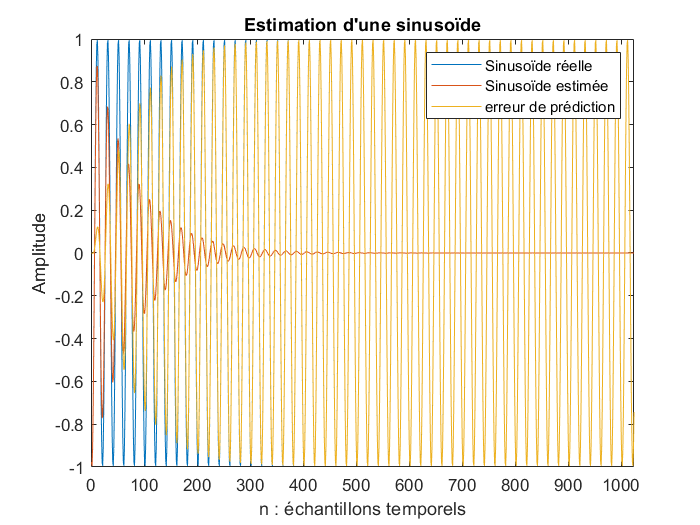


plot(VectN, Sin)

hold on

plot(VectN, SinEstim)

plot(VectN, erreurPredict)

xlabel("n : échantillons temporels")
ylabel("Amplitude")
xlim([0, N])

legend("Sinusoïde réelle", "Sinusoïde estimée", "erreur de prédiction")

title("Estimation d'une sinusoïde")

hold off

Autocorrélation de l'erreur de prédiction sur sinusoïde

[AutoErr, pVectErr] = BiasedCrossCorr(erreurPredict)

AutoErr =     0.4473    0.4252    0.3615    0.2625    0.1379   -0.0001   -0.1379   -0.2620   -0.3603   -0.4232   -0.4446   -0.4225   -0.3590   -0.2605   -0.1365    0.0006    0.1375    0.2608    0.3583    0.4207    0.4418    0.4196    0.3563    0.2583    0.1351   -0.0011   -0.1371   -0.2594   -0.3561   -0.4179   -0.4386   -0.4164   -0.3534   -0.2560   -0.1336    0.0017    0.1366    0.2579    0.3537    0.4148    0.4352    0.4130    0.3504    0.2535    0.1320   -0.0022   -0.1360   -0.2562   -0.3512   -0.4116


pVectErr =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


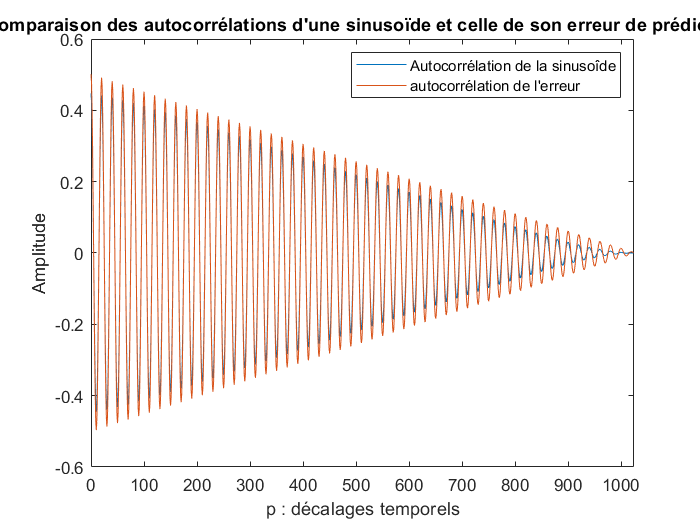



plot(pVectErr, AutoErr)

xlabel("p : décalages temporels")
ylabel("Amplitude")
xlim([0, N])

title("Comparaison des autocorrélations d'une sinusoïde et celle de son erreur de prédiction")

hold on

plot(pVectSin, CxSin)

legend("Autocorrélation de la sinusoîde", "autocorrélation de l'erreur")

hold off

Lecture des sons voisé / non-voisé de moodle

%load("193305__margo-heston__ch.flac")

[son1, Fe1] = audioread("193309__margo-heston__ooo.flac")

son1 =          0    0.0000
   -0.0001    0.0001
   -0.0001    0.0001
   -0.0001         0
    0.0000   -0.0000
         0    0.0000
   -0.0001    0.0001
   -0.0001    0.0001
   -0.0000         0
    0.0000   -0.0000


Fe1 = 44100


son1 = son1.'

son1 =          0   -0.0001   -0.0001   -0.0001    0.0000         0   -0.0001   -0.0001   -0.0000    0.0000         0   -0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0000         0   -0.0001   -0.0001   -0.0000   -0.0000    0.0000         0         0   -0.0000
    0.0000    0.0001    0.0001         0   -0.0000    0.0000    0.0001    0.0001         0   -0.0000    0.0000         0   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000         0    0.0001    0.0002    0.0001         0    0.0001    0.0001    0.0001    0.0000         0   -0.0000         0    0.0000  

son1 = son1(1, :)

son1 =          0   -0.0001   -0.0001   -0.0001    0.0000         0   -0.0001   -0.0001   -0.0000    0.0000         0   -0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0000         0   -0.0001   -0.0001   -0.0000   -0.0000    0.0000         0         0   -0.0000


Vectson = 1 : length(son1);
%son1 = son1(600 : N+599)

[Cx1, pVect1] = UnbiasedCrossCorr(son1)

Cx1 =     0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0029    0.0029    0.0029    0.0028    0.0027    0.0027    0.0026    0.0025    0.0024    0.0023    0.0023    0.0022    0.0021    0.0020    0.0019    0.0017    0.0016    0.0015    0.0014    0.0013    0.0012    0.0010    0.0009    0.0008    0.0007    0.0006    0.0004    0.0003    0.0002    0.0001   -0.0000   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0011   -0.0012   -0.0013


pVect1 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



bool1 = isVoiced(Cx1, Fe1)

bool1 = 1


K1 = 10 ;
K2 = 30 ;
[a1, v1] = YuleWalkerSolver(Cx1, K1)

MatCov =     0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0029    0.0029    0.0029    0.0028
    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0029    0.0029    0.0029
    0.0031    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0029    0.0029
    0.0030    0.0031    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0029
    0.0030    0.0030    0.0031    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030    0.0030
    0.0030    0.0030    0.0030    0.0031    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030
    0.0029    0.0030    0.0030    0.0030    0.0031    0.0031    0.0031    0.0031    0.0031    0.0030
    0.0029    0.0029    0.0030    0.0030    0.0030    0.0031    0.0031    0.0031    0.0031    0.0031
    0.0029    0.0029    0.0029    0.0030    0.0030    0.0030    0.0031    0.0031    0.0031    0.0031
    0.0028    0.0029    0.0029    0.0029    0.0030    0.0030    0.0030    0.0031  

a1 =     2.1879
   -1.2508
   -0.8772
    1.6653
    0.1316
   -1.7399
    0.6286
    1.5766
   -2.3121
    0.9896


v1 = 5.1470e-08

[a2, v2] = YuleWalkerSolver(Cx1, K2)

MatCov =     0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0029    0.0029    0.0029    0.0028    0.0027    0.0027    0.0026    0.0025    0.0024    0.0023    0.0023    0.0022    0.0021    0.0020    0.0019    0.0017    0.0016    0.0015    0.0014    0.0013    0.0012    0.0010    0.0009    0.0008
    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0029    0.0029    0.0029    0.0028    0.0027    0.0027    0.0026    0.0025    0.0024    0.0023    0.0023    0.0022    0.0021    0.0020    0.0019    0.0017    0.0016    0.0015    0.0014    0.0013    0.0012    0.0010    0.0009
    0.0031    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0029    0.0029    0.0029    0.0028    0.0027    0.0027    0.0026    0.0025    0.0024    0.0023    0.0023    0.0022    0.0021    0.0020    0.0019    0.0017    0.0016    0.0015    0.0014    0.0013    0.0012    0.0010
    0.0030    0.0031    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030    0.00

a2 =     1.2923
    0.7180
   -1.7923
    0.4671
    1.6890
   -1.1442
   -1.7013
    1.4246
    1.5175
   -1.5381


v2 = 1.5915e-07


Son1EstimK1 = filter(a1, 1, son1)

Son1EstimK1 =          0   -0.0001   -0.0002    0.0001    0.0001   -0.0002   -0.0002    0.0001    0.0000   -0.0001   -0.0000    0.0000    0.0001    0.0001   -0.0001    0.0001    0.0002   -0.0001   -0.0001    0.0002    0.0001   -0.0001    0.0000    0.0002    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001   -0.0000    0.0001    0.0002   -0.0001   -0.0000    0.0001   -0.0001   -0.0003    0.0000    0.0001   -0.0002   -0.0002    0.0000    0.0001   -0.0001   -0.0000    0.0002   -0.0000   -0.0002


Son1EstimK2 = filter(a2, 1, son1)

Son1EstimK2 =          0   -0.0001   -0.0002   -0.0001    0.0002   -0.0000   -0.0003   -0.0000    0.0002   -0.0000   -0.0003    0.0000    0.0004    0.0001   -0.0002    0.0001    0.0004   -0.0000   -0.0004    0.0001    0.0005   -0.0001   -0.0004    0.0002    0.0005   -0.0002   -0.0003    0.0003    0.0004   -0.0001   -0.0001    0.0002    0.0002   -0.0000   -0.0002    0.0001    0.0002   -0.0002   -0.0004   -0.0001    0.0002   -0.0000   -0.0003   -0.0002    0.0003    0.0001   -0.0004   -0.0000    0.0004   -0.0001


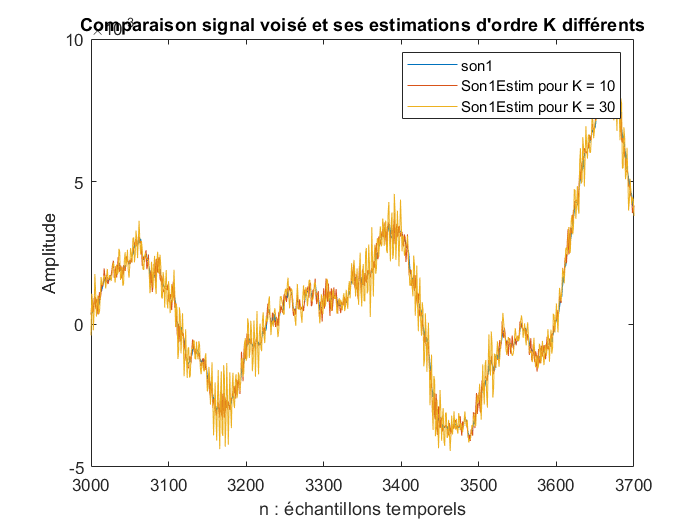


plot(Vectson, son1)

hold on 

plot(Vectson,Son1EstimK1)

plot(Vectson, Son1EstimK2)

xlim([3000, 3700])
xlabel("n : échantillons temporels")
ylabel("Amplitude")
title("Comparaison signal voisé et ses estimations d'ordre K différents")

legend("son1", "Son1Estim pour K = 10", "Son1Estim pour K = 30 ")

hold off



% % K1 = 1;
% % 
 %[a1, v1] = YuleWalkerSolver(Cx1, 1)
% % 
% % Son1EstimK1 = zeros(1,N);
% % B1 = BruitBlanc(N, v1)
% % for i = 1 : K1
% %     Son1EstimK1(i)=son1(i);
% % end
% % for n = 1 : N-1
% %          Son1EstimK1(n+1) = a1*Son1EstimK1(n) + B1(n+1);
% % end
%    
% K2 = 2;
% 
% [a2, v2] = YuleWalkerSolver(Cx1, 2)
% Son1EstimK2 = zeros(1,N);
% 
% for i = 1 : K2
%     Son1EstimK2(i)=son1(i);
% end
% for m = 1 : N-2
%     Son1EstimK2(m+2) = a2(1)*Son1EstimK2(m+1) + a2(2)*Son1EstimK2(m);
% end
% 
% plot(VectN, son1)
% 
% hold on 
% 
% plot(VectN,Son1EstimK1)
% 
%  plot(VectN, Son1EstimK2)
% 
% legend("son1", "Son1EstimK1", "Son1EstimK2")
% 
% hold off

%erreurPredict(1:N) = Sin(1:N) - SinEstim(1:N)


Kchoisit = 30;
[aforKchoisit, v30] = YuleWalkerSolver(CxSin, Kchoisit);

MatCov =     0.5013    0.4762    0.4045    0.2935    0.1539   -0.0004   -0.1544   -0.2930   -0.4027   -0.4727   -0.4964   -0.4715   -0.4006   -0.2906   -0.1524    0.0004    0.1529    0.2901    0.3987    0.4681    0.4915    0.4669    0.3966    0.2877    0.1509   -0.0004   -0.1514   -0.2873   -0.3948   -0.4634
    0.4762    0.5013    0.4762    0.4045    0.2935    0.1539   -0.0004   -0.1544   -0.2930   -0.4027   -0.4727   -0.4964   -0.4715   -0.4006   -0.2906   -0.1524    0.0004    0.1529    0.2901    0.3987    0.4681    0.4915    0.4669    0.3966    0.2877    0.1509   -0.0004   -0.1514   -0.2873   -0.3948
    0.4045    0.4762    0.5013    0.4762    0.4045    0.2935    0.1539   -0.0004   -0.1544   -0.2930   -0.4027   -0.4727   -0.4964   -0.4715   -0.4006   -0.2906   -0.1524    0.0004    0.1529    0.2901    0.3987    0.4681    0.4915    0.4669    0.3966    0.2877    0.1509   -0.0004   -0.1514   -0.2873
    0.2935    0.4045    0.4762    0.5013    0.4762    0.4045    0.2935    0.1539   -0.00


Son1EstimK = zeros(1,N)

Son1EstimK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


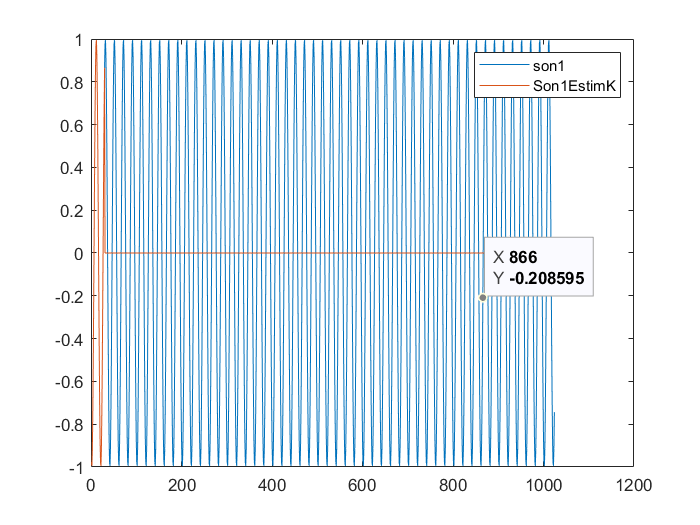

for n = 1 : Kchoisit
    Son1EstimK(n)=Sin(n);  %On remplit les K premières valeurs
end
for i = Kchoisit : N-1
    for a = 0 : length(aforKchoisit)-1
        Son1EstimK(i+1) = Son1EstimK(i-a)*aforKchoisit(a+1);  %On prédit le signal
    end
end

plot(VectN, Sin)

hold on 

plot(VectN,Son1EstimK )

legend("son1", "Son1EstimK")

hold off